# Tutorial 2 - ENSO (El Nino - Southern Oscillation)

What you will need from Canvas:

- noaa_psl_indices_soi.txt

- sst.mon.mean_1982.01-2020.12.nc

- findnearestval.m (function to find nearest values in a vector of numbers)

Additonally you need the following toolboxes installed (remember to have everything added to the Matlab search path) :

- jlab ([ https://www.mathworks.com/matlabcentral/fileexchange/52885-jlab-a-matlab-toolbox-for-data-analysis](https://www.mathworks.com/matlabcentral/fileexchange/52885-jlab-a-matlab-toolbox-for-data-analysis)) 

- Climate Data Toolbox ( [https://www.mathworks.com/matlabcentral/fileexchange/70338-climate-data-toolbox-for-matlab](https://www.mathworks.com/matlabcentral/fileexchange/70338-climate-data-toolbox-for-matlab) )

- cmocean ( [https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps](https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps) )

Throughout the notebook, key tasks will be indicated as follows:

**!! Q0***** -*** ***Look for tasks like these. There are 12 in this livescript.***

Please be sure to complete these tasks, as we will be checking for their  completion while marking.

Work through the livescript, and export this as html and/or as pdf, which will be your report in addition to your live script. For the final report that you hand in, only keep the important parts and delete the rest of the code.

Make sure that the file contains:

- Well-documented code

- Your answers to specific questions asked within the script

- Your figures with proper labeling, i.e. axis and colorbar labels, as well as titles and legends (where needed). Add figure captions for each figure (They can be added as text below the figure in the live script)

- short description on the figures and their interpretation as specified within the live script.

Please include your name in the file name, e.g. ENSO_GlennLiu.mlx.

Check the list at the end of the notebook for additional submission instructions. 

## Loading the Southern Oscillation Index (SOI) Dataset

The full dataset is the Southern Oscillation Index from 1876 to present and is available at [http://www.bom.gov.au/climate/enso/soi/](http://www.bom.gov.au/climate/enso/soi/)[.](http://www.bom.gov.au/climate/current/soi2.shtml.) We will be working with a subset of this data from 1982 to 2020 ("noaa_psl_indices_soi.txt"), downloaded from NOAA's Climate Indices time series (https://psl.noaa.gov/data/climateindices/list/).

**!! Q1 - ***Give a short explanation what the SOI represents (Hint: check out *[*http://www.bom.gov.au/climate/glossary/soi.shtml*](http://www.bom.gov.au/climate/glossary/soi.shtml)*)*

**Type your answer here: **The Southern Oscillation Index represents the difference in air pressure experienced in Tahiti and Austrailia in the Atlantic ocean, and helps determine the intensity of the ENSO event each year 

clear all, close all % clear workspace and close all windows
load noaa_psl_indices_soi.txt;
whos

  Name                        Size            Bytes  Class     Attributes

  noaa_psl_indices_soi      468x2              7488  double              



The text file contains two columns. Column 1 is the date , column 2 is the Southern Oscillation Index (SOI). For convenience, we can split up the data into two variables and delete the original variable

soi = noaa_psl_indices_soi(:,2);
soi_time = noaa_psl_indices_soi(:,1);
clear noaa_psl_indices_soi

soi_time;

## Plotting the SOI Index

Use the* plot* function to plot the SOI versus time. In addition to the original data, use mov*mean* or *vfilt (from jlab)* to plot a smoothed/low-pass filtered time series on top. Remember, you need *hold on *to plot multiple lines in one plot. Use *help* to learn more about the functions. For an alternative plot use the *bar* function.

% create new blank figure
figure(1);clf; hold on
plot(soi_time,soi)
plot(soi_time,movmean(soi,2),'r','linewidth',2)
plot(soi_time,movmean(soi,10),'g','linewidth',2)



**Your task:**

**!! Q2 -** Run the code above to make a plot of the SOI Index. Complete the following:

- Try adjusting the running mean window (see movmean())

- Add axis labels and a legend

- Add a zero line (Hint: try *hline (CDT) or hlines(jlab)*

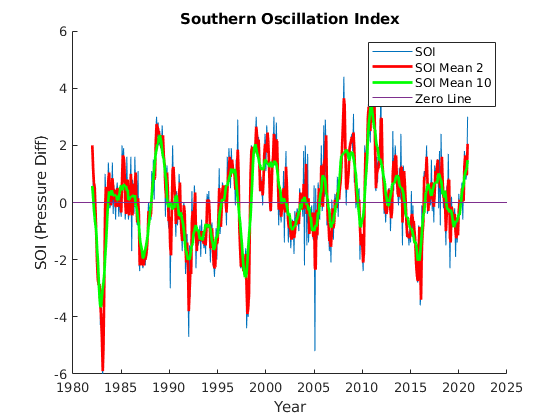

% add code here
hold on
xlabel('Year')
ylabel('SOI (Pressure Diff)')
title('Southern Oscillation Index')

%Y = movmean(soi,2)
hline(0)
legend('SOI','SOI Mean 2','SOI Mean 10','Zero Line')

Note that the plot above is very basic. With a little bit of effort we can often make the plot much more comprehensible and visually appealing. 

For exampe, check out the *anomaly* function that is part of the CTD toolbox below. You can open the anomaly.m file within the CDT toolbox to investigate the function for further details.

figure(1),clf
anomaly(soi_time,vfilt(soi,3))
grid on
box on  % closed box
xlim([soi_time(1) soi_time(end)]) % set xlimit to time range

## Histogram

Next, we will plot a histogram of the index. 

**!! Q3 -** *Give a short explanation of what the histogram tells us about the data. Try both options by uncommenting the second command and choose a bin size that you think is most suitable.*

figure(2),clf
hist(soi)
%hist(soi,-40:5:40)
grid on

**Answer:**

## Sea Surface Temperature (SST) Data and the netCDF Format

We will now load in and work with monthly mean SST data from the Optimum Interpolation SST (OISST) dataset (https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html). The data is on a 1/4 degree global grid, and we will be working with a subset between 1982 and 2020.

One of the most common formats you will encounter while working with Climate data is the **netCDF format** (https://www.unidata.ucar.edu/software/netcdf/). These files can store/compress numerous types of multi-dimensional variables, and generally contain metadata that describes its contents in detail. Let's begin by using **ncdisp() **to view the contents of the netCDF file.

% you can also try ncinfo(), which loads this metadata into a struct
ncname = "sst.mon.mean_1982.01-2020.12.nc";
ncdisp(ncname)

A properly documented netCDF generally has information on the variable names, units, dimensions, and other attributes. Now that we are aware of the contents of the netCDF file, we will now load in the variables we want (*sst, longitude, latitude, time*) using **ncread()**. Note that this make take some time, as the dataset is quite large.

sstout = ncread(ncname,"sst");
time   = ncread(ncname,"time");
lat    = ncread(ncname,"lat");
lon    = ncread(ncname,"lon");

whos

Let's take a closer look at the time variable, which is given in decimal years (same as the SOI Index)

format long % type 'help format' into command line
time(1)

This means 1982 plus 0.041095 years

**!! Q4 - ***What is 0.041095 years in days and what day of the year are the 2nd and 3rd time taken?*

**Answer:**

One useful operation to familiarize yourself with is permute(), which swaps the orders of the dimensions. For example, the **sstout **variable is currently *[longitude x latitude x time]*. Run the section below to change it to *[time x longitude x latitude]:*

sst = permute(sstout,[3,1,2]); % The second argument indicates that new order of the original dimensions.
size(sst)

## **Plotting SST**

We will create map plots to show 2-D data. The easiest way to do this is using the *pcolor* command. If you get an error message that the dimensions do not agree, you have to use ' to transpose the *sst* array.

% plot sst at first time step (remember time is the first dimension)
figure(3)
pp = pcolor(lon,lat,squeeze(sst(1,:,:))');
pp.EdgeColor = 'none';
colorbar
set(gca,'layer','top') %  What does this command do?


**!! Q5** - What do the *edgecolor* (a more simple way is to use *shading flat *instead) and *squeeze* commands do? 

**Answer:**

## **Animating SST Maps**

For a quick **animation** you can paste the following code in the command window (This will not work in the live script). Alternatively, you can select the code and press F9. Press any key to jump to the next figure in the loop. To cancel out of the animation, use CTRL+C. This is generally useful for cancelling MATLAB code executions

figure(3),clf
for t = 1:length(time)
    pcolor(lon,lat,squeeze(sst(t,:,:))')
    shading flat
    colorbar
    pause
end


When you run the loop above, you will notice that the colorbar limits change, which makes it hard to interpret what we see. 

- use the *caxis *command

- try adding a title that shows the changing date. Hint: you will need to use the *num2str* function introduced in the Matlab-Intro tutorial.

**!! Q6 - **Your next task is to plot the time-mean SST. To do this, take an average across the time dimension for the sst matrix. (Hint: you will need to average across all times, i.e. the first dimension of the sst matrix. Look into the mean() function.)

- Add title, labels, colorbar etc.

- Also add a label to the colorbar (Try cb = colorbar, cb.Label.String = '...')

% Place your code here:


## **Plotting the seasonal cycle**

In the next step, we will look at the seasonal cycle of SST. For this we need to choose all Januaries, all Februarys etc and then average. 

To plot the mean SST for all Februarys you could do:

figure(5),clf
pcolor(lon,lat,squeeze(mean(sst(2:12:end,:,:)))');shading flat
cb = colorbar;
cb.Label.String = 'sst';
title('Mean February SST')
set(gca, 'Layer', 'top');   

**!! Q7 - **Write a loop to plot the mean SST for each month. The loop should:

- Include a title that indicates the current month Hint: *title(['month=', num2str(...)])*

- *Label all axes*

- *Include a colorbar with consistent colorlimits (use caxis to control the colormap limits)*

% place your code here:



These 12 monthly averages are called a **climatology of SST** (i.e. average temperature for jan, feb ...). We can create a new variable that contains the SST climatology:

for m = 1:12  %loop over month
    climSST(m,:,:) = mean(sst(m:12:end,:,:));
end
whos climSST

We can see that the new variable has the dimensions month,lon,lat.

NOTE: One way to compute the climatology without looping is to  "reshape" the matrix, unstacking the timeseries into month x year dimensions. This tends to work when you have the full 12-months of data  for multiple years.

See below for an example:

[ntime,nlon,nlat] = size(sst);% Get size of sst
nyrs = round(ntime/12);% Determine # of years
sst_mon   = reshape(sst,12,nyrs,nlon,nlat);% Reshape to separate month and year
climSST2  = squeeze(mean(sst_mon,2));% Take mean along year dimension
nanmax(abs(climSST2(:)-climSST(:)))% Check to make sure the mean absolute difference is 0 (between the two methods)

Rather than plotting each month in individal figures, we can plot them all in one plot using the *subplot * command:

% fill in the code
figure(6),clf,hold on
for m = 1:12
    subplot(3,4,m)
    % pcolor(...
    % caxis(...
    % colorbar ...
    % title( ...
end

**SST anomalies**

The climatology tells us what temperature we might expect in each month on average. But, of course, in any given month it could be warmer or colder than the long-term average. The difference is called an **anomaly.**

Next, we produce a variable that contains SST anomalies, i.e. the difference between SST at a given month and the SST climatology. This tells us how much hotter or colder than normal temperature is for each month.

To do this we need to get the SST for a particular month and subtract the corresponding climatological SST for that month. For example:

sst(1,:,:);       % SST for January 1961
climSST(1,:,:);   % average SST for all Januarys

% SST anomaly for January 1961:
ssta_1961_1 = sst(1,:,:)-climSST(1,:,:);
% SST anomaly for January 1962:
ssta_1962_1 = sst(13,:,:)-climSST(1,:,:);

Of course, we don't want to type all this code. There are several ways you can do these kind of calculations. This will, in the end, depend on your way of thinking and programming style. See below for two examples:

% Example Method 1: Using a Loop
% initialize/preallocate an array full of nan with the same size as sst
anomSST = nan(size(sst));
for i = 1:12
    anomSST(i:12:end,:,:) = sst(i:12:end,:,:) - climSST(i,:,:); 
end

% Example Method 2: Using repmat 
% starting our earlier, reshaped arrays... (sst_mon)
climSSTrep = repmat(climSST2,1,1,1,nyrs); % Use remap to repeat the matrix "nyr" times along the last dimension
climSSTrep = permute(climSSTrep,[1,4,2,3]); % Permute back to [mon x year x lon x lat]
anomSST2   = sst_mon - climSSTrep; % Calculate anomaly

% Check to make sure the mean absolute difference is 0 (between the two methods)
nanmax(abs(anomSST2(:)-anomSST2(:)))

**Plotting SST anomalies**

Let's plot to see if the code works:

figure(7),clf
pcolor(lon,lat,squeeze(anomSST(1,:,:))')
shading flat
colorbar
set(gca, 'Layer', 'top');
grid on
caxis([-3 3])
cmocean('balance','pivot')

**!! Q8** - *Describe the SST anomalies!*

**Answer**

## Compare SST with SOI

Now we can investigate the relationship between SST and SOI.

Lets choose a date, where the SOI is in a negative phase and plot the sst anomalies. For this you can use the function *findnearestval *that was provided together with this tutorial. Here is an example:

% lets find the index for sst anomaly  Janaury 1998
index = findnearestval(1998,time)
% test if index represents time you want
time(index)

% lets plot the sst field
figure(4),clf
pcolor(lon,lat,squeeze(anomSST(index,:,:))')
shading flat
colorbar
caxis([-3 3])
set(gca, 'Layer', 'top');
title(['sst anomaly ' sprintf('%4.3f',time(index))]) % check out sprintf
cmocean('balance','pivot') % What does 'pivot' do?

**!! Q9***** - ****Pick another date where SOI was in a positive phase*

- Plot both maps in one figure (incl. the one above), using subplot

- Give a short description of what you see and compare the positive and negative phases.

% place your code here

**Answer**

Now we can look at particular locations.

Find the index of the latitude closest to the equator and the longitude closest to 240E. Hint: Use the function *findnearestval*

%lat_0 = ...
%lon_240 = ...


% create a variable that contains the timeseries of SST anomalies at 240E on the equator
%anomSST_0_240E=....

**!! Q10 - ***Create a 2 panel figure, with the top panel showing the SOI timeseries and the bottom panel showing the anomaly timeseries that we just derived.*

- Add a 6-month moving average/ low-pass filter on top of both time series (remember the *hold on *command)

- OPTIONAL: You can also try to create an additional figure using the *anomaly *(see above) again.

% Place your code here for subplot
figure(6),clf
subplot(2,1,1)
subplot(2,1,2)


**!! Q11 ** - *Plot a scatterplot of SOI versus your anomaly time series*

- Give a short explanation what this plot tells you

- Click on the arrow in the top right corner of the figure to open the figure in a window. On the figure window, click on the Tools menu > Basic Fitting > Linear > Show equation . This will add a trend line for you. However, the actual plotting of a trend line is also not difficult. Check out *polyfit *and *polyval *in the Matlab help.

% Place your code here for scatter plot
figure(7),clf

**Answer**

As a final step we can calculate the correlation between the SOI and anomSST_0_240E and the associated p-value. For those of you who haven't done much statistics, look up what the p-value means. It is extremely important in science for testing hypotheses.

[r,p] = corr(soi,anomSST_0_240E)
format short
r,p

## Your report

Your final report should only contain the important plots. You may want to create two files: one for yourself that includes everything above and one for submission that only includes the relevant material. This should include:

- a plot of the SOI ( and maybe a histogram plot)

- plot of mean SST

- plot of the seasonal cycle of SST

- plot the SST anomaly in January 1998 and at a time when the SOI was in a different phase

- scatterplot between SOI and the SST anoamly at 240E on the equator

- all answers to questions asked throughout (including Q12 below)

- remember labels etc. and figure captions.

**!! Q12**  - Give a brief description of El Nino and La Nina SST and how these relate to the SOI (max 300 words)

The above are recommended plots but you are free to play with the data and produce whatever plots you think might be interesting for linking the SOI and SST.

## Optional extras (unmarked)

For those of you who are after a challenge or who who think they will use matlab in the future, here are some extra things you could try:

- Write a code that will plot a map of the seasonal range in SST (i.e. the difference between the maximum and minimum climatological SST)

- Find all the dates when the SOI is big (e.g. > 1 standard deviation) and plot the average SST anomaly for these dates. Repeat for small values of the SOI. (This is called a **composite analysis**)

- Try using the contourf command instead of pcolor command. This can produce much cleaner figures

- The *findearestval *function finds the location of the nearest value to a given value in a matrix. This is based on the following command: [Y,I] = min(abs(time-2000)). Try it out and see how it works. Doing these calculations yourself without using an external function, makes your code more transparent.